# Group Assignment 5 - Edge detection using second order gradients, Image Segmentation using clustering

By Amanda Chang, Dokyun Kim, Jun Park

img1 = imread("../../pictures/nyc.jpg");
img2 = imread("../../pictures/olin.jpeg");

**1) Second Order Gradient (total 40 points)**

- Apply Laplace of Gaussian (LoG) to your images to find edges (10)

- Apply Canny edge detector to your images to detect edges (10)

- Comment on how well each of them work on your images (20)

**2) Image Segmentation using clustering (total 30 points)**

- Apply k-means algorithm to your images.(10)

- How many clusters seem to work well for your images? (10)

- What parameters did you use? (e.g. R, G, B, H, S, V....). Did these work well? (10)

- Just for your own learning: Can you apply mean-shift clustering to your images? (0 points)

**3) Corner detection (total 20 points)**

- try out the inbuilt corner detection functions in MATLAB and Python on both your images. (10 points)

- Did you need optimize the "number" of corners to be found for better accuracy? Explain. (10 points)

**4) Hough transform (total 20 points)**

- try out the inbuilt hough transform functions (in MATLAB they are: hough, houghpeaks, houghlines) to detect lines in your image. (20 points)

- What did you need to optimize to find the lines you wanted to find? (10 points)

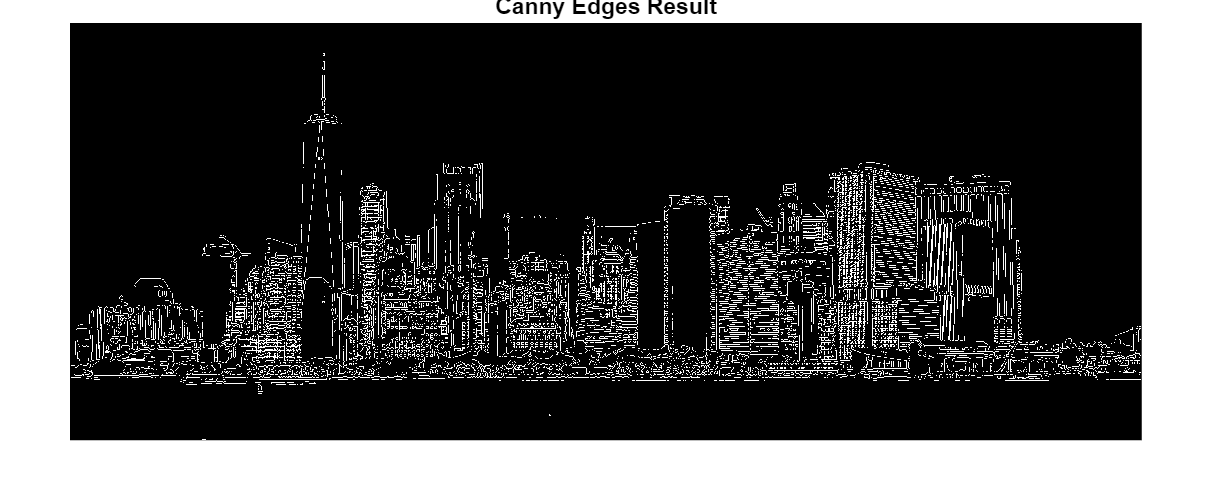

I1 = im2gray(img1);
[BW1, TH1] = edge(I1, "canny", [0.07, 0.2]);
[H1,theta1,rho1] = hough(BW1);
P1 = houghpeaks(H1,10,'threshold',ceil(0.3*max(H1(:))));
lines1 = houghlines(BW1,theta1,rho1,P1,'FillGap',5,'MinLength',10);
figure, imshow(BW1), title("Canny Edges Result");

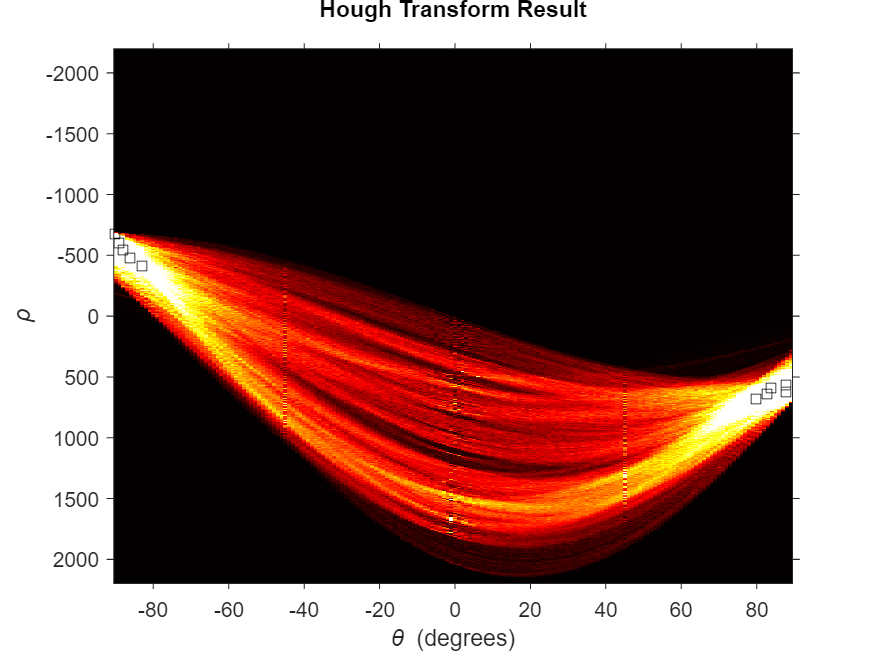

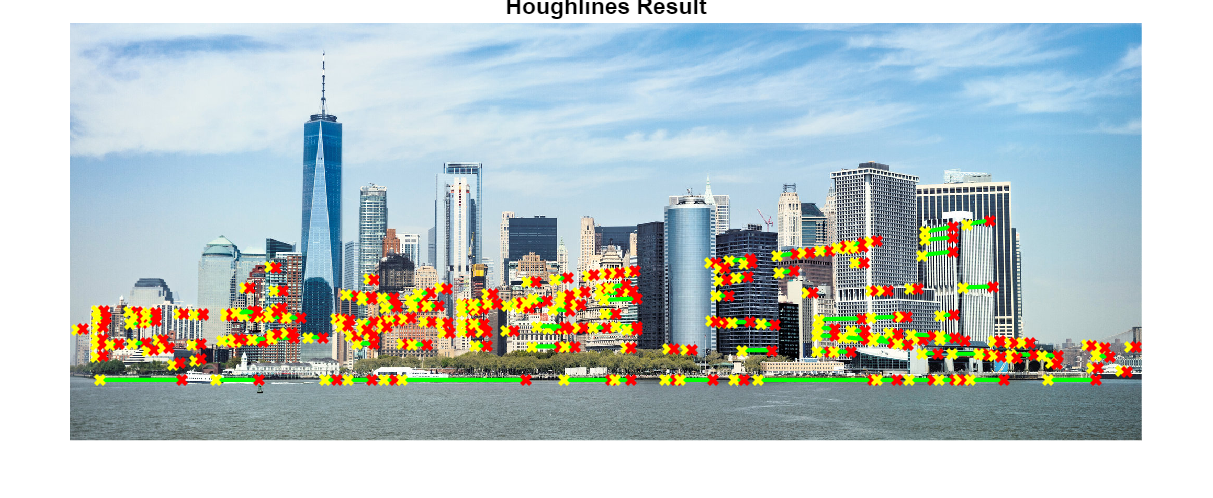

dispHough(img1, H1, theta1, rho1, P1, lines1);

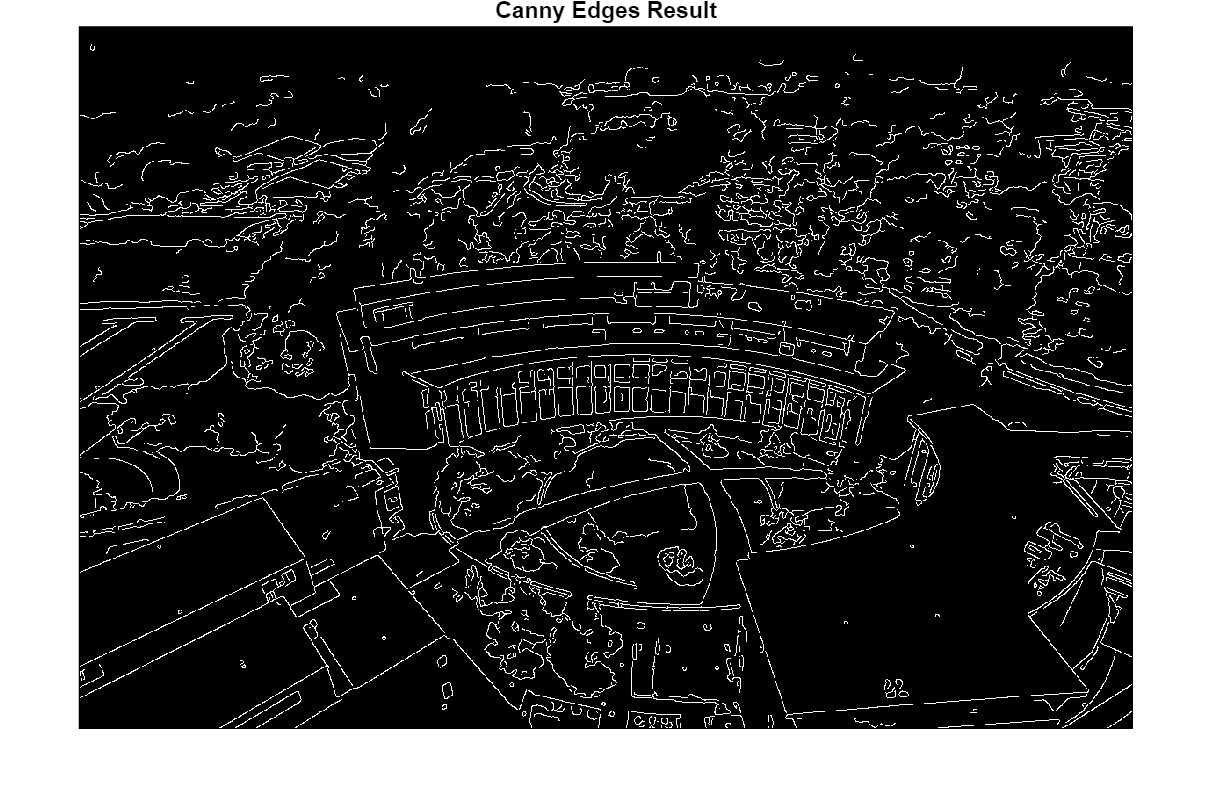

I2 = im2gray(img2);
[BW2, TH2] = edge(I2, "canny", [0.1, 0.2]);
[H2,theta2,rho2] = hough(BW2);
P2 = houghpeaks(H2,15,'threshold',ceil(0.3*max(H2(:))));
lines2 = houghlines(BW2,theta2,rho2,P2,'FillGap',5,'MinLength',10);
figure, imshow(BW2), title("Canny Edges Result");

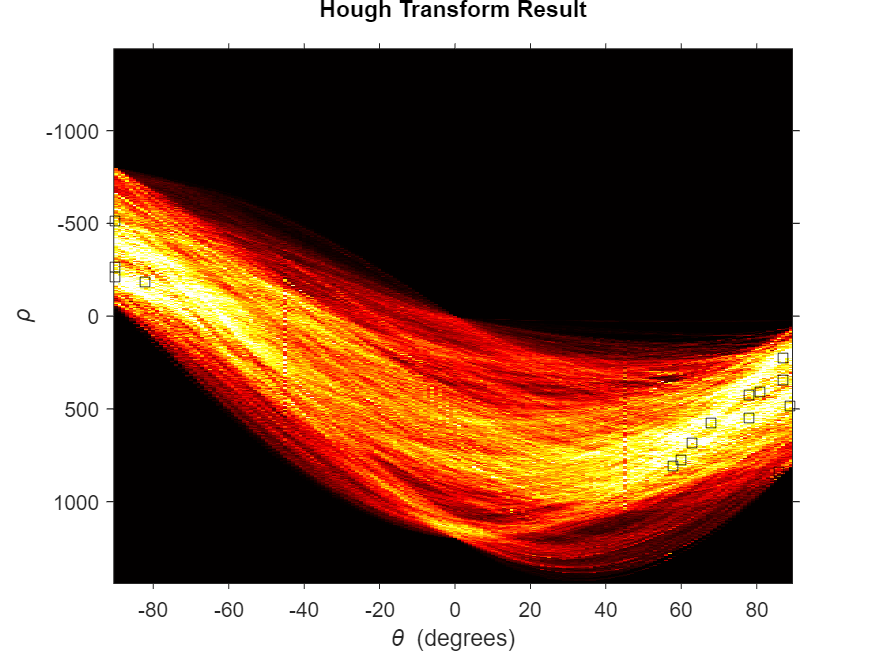

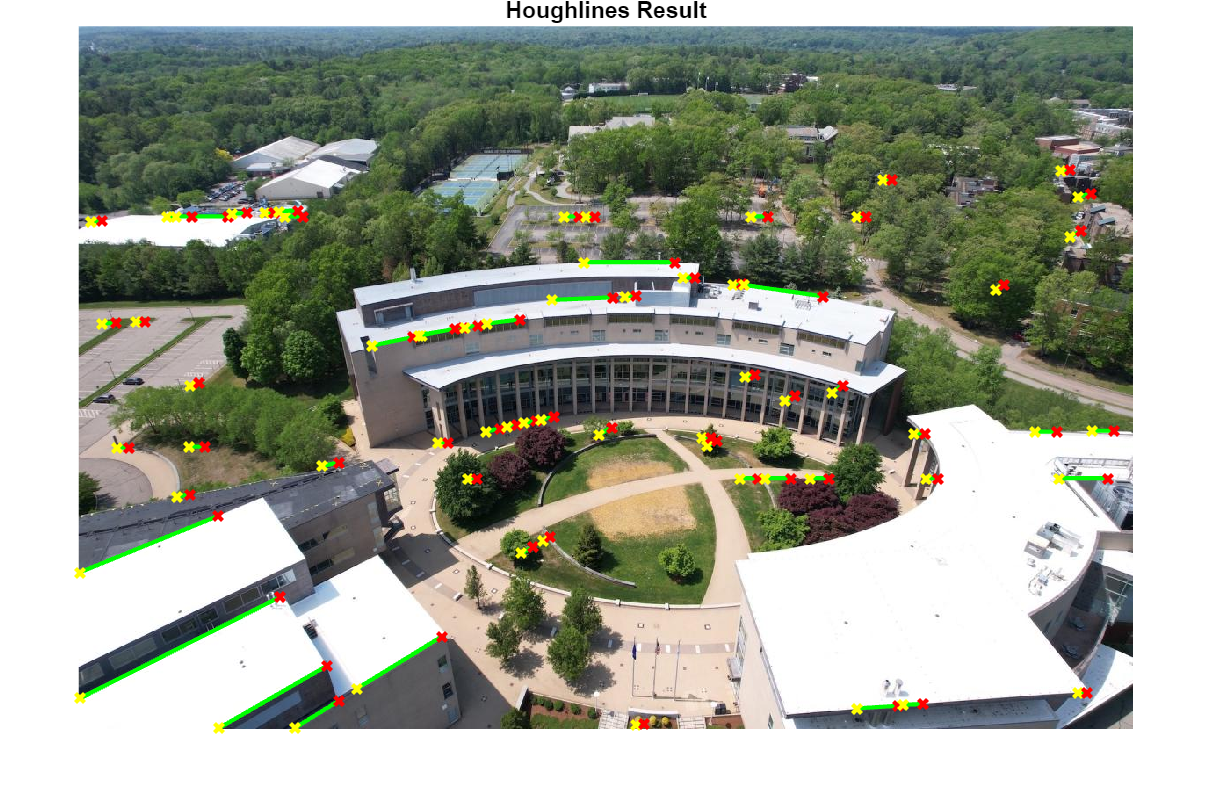

dispHough(img2, H2, theta2, rho2, P2, lines2);

To get the lines I wanted, there were multiple parameters I had to test around with.

- Canny Edge threshold values; Since `hough()` takes in edges as a parameter, it was important to tune the canny edge thresholds so the lines I want to capture are represented well in the result.

- Number of peaks in `houghpeaks`; When I wanted to capture some of the weaker lines, increasing this parameter helped capture some of those lines.

- Minlength for `houghlines`; When I wanted to ignore short lines, I increased this to focus more on the longer lines in the image.

**5) Applying various concepts together (40 points)**

We have learned many concepts in image processing now. Use a combination of those concepts and methods to find letters in the given image. (hint: it is a blurred image, letters have lines, corners, edges, the board has different colors on it).

img = imread('../../pictures/scrabble.jpg');

function dispHough(img, H, theta, rho, P, lines)
    figure
    imshow(imadjust(rescale(H)),[],'XData',theta,'YData',rho, 'InitialMagnification','fit');
    xlabel('\theta (degrees)')
    ylabel('\rho')
    title("Hough Transform Result", 'Units', 'normalized', 'Position', [0.5, 1.05, 0])
    axis on
    axis normal 
    hold on
    colormap(gca,hot)
    
    x = theta(P(:,2));
    y = rho(P(:,1));
    plot(x,y,'s','color','black');
    
    figure, imshow(img), hold on
    for k = 1:length(lines)
       xy = [lines(k).point1; lines(k).point2];
       plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
    
       % Plot beginnings and ends of lines
       plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
       plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
    end
    title("Houghlines Result")
end